X-axis Control - Correlation Between X-Axis Servo Rotation & Thrust Vector Angle

Inputs:

theta1 = 3; %degrees

X_Axis_Control_Arm_Length = 0.329; 
X_Axis_Linkage_Length = 1.071;
X_Axis_Radius_Of_Rotation = 1.123;

Y_Axis_Control_Arm_Length = 0.329;
Y_Axis_Linkage_Length = 0.9913; 
Y_Axis_Radius_Of_Rotation = 1.106; 

These Equations Model the X-Axis Servo Dual Linkage System:


$$C \sin(\theta_1) + L \cos(\theta_2) = L + R \sin(\phi) \\
C \cos(\theta_1) + L \sin(\theta_2) = R \cos(\phi) - (R - C)


$$


%% X-axis Control - Correlation Between Servo Rotation & Thrust Vector Angle
theta1 = deg2rad(theta1);
C_Xaxis = X_Axis_Control_Arm_Length;
L_Xaxis = X_Axis_Linkage_Length;
R_Xaxis = X_Axis_Radius_Of_Rotation;

%%Set up System of Nonlinear Equations x(1) = theta2, x(2) = phi
eqs = @(x)[
  C_Xaxis*sin(theta1) + L_Xaxis*cos(x(1))-L_Xaxis-R_Xaxis*sin(x(2));
  C_Xaxis*cos(theta1) + L_Xaxis*sin(x(1))-R_Xaxis*cos(x(2))+R_Xaxis-C_Xaxis
];

%initial guesses
x0 = [0;0];

% Solve the system
options = optimoptions('fsolve', 'Display', 'off');
sol = fsolve(eqs, x0, options);

%Convert Everything Back to Degrees
theta1 = rad2deg(theta1);
theta2 = rad2deg(sol(1));
phi = rad2deg(sol(2));

% Display result
fprintf('X-Axis Servo Angle (θ₁): %.2f°\n', theta1);

X-Axis Servo Angle (θ₁): 3.00°


fprintf('X-Axis Linkage Angle (θ₂): %.2f°\n', theta2);

X-Axis Linkage Angle (θ₂): 0.02°


fprintf('X-Axis Thrust Vector Angle (ϕ): %.2f°\n', phi);

X-Axis Thrust Vector Angle (ϕ): 0.88°


Y-axis Control - Correlation Between Y-Axis Servo Rotation & Thrust Vector Y-axis Angle

These Equations Model the Y-Axis Servo Dual Linkage System:


$$C \sin(\theta_1) + L \cos(\theta_2) = L + R \sin(\phi) \\
C \cos(\theta_1) + L \sin(\theta_2) = R+C-R\cos(\phi)


$$



theta1 = deg2rad(theta1);
C_Yaxis = Y_Axis_Control_Arm_Length;
L_Yaxis = Y_Axis_Linkage_Length;
R_Yaxis = Y_Axis_Radius_Of_Rotation;

%%Set up System of Nonlinear Equations x(1) = theta2, x(2) = phi
eqs = @(x)[
  C_Yaxis*sin(theta1) + L_Yaxis*cos(x(1))-L_Yaxis-R_Yaxis*sin(x(2));
  C_Yaxis*cos(theta1) + L_Yaxis*sin(x(1))-R_Yaxis-C_Yaxis+R_Yaxis*cos(x(2))
];

%initial guesses
x0 = [0;0];

% Solve the system
options = optimoptions('fsolve', 'Display', 'off');
sol = fsolve(eqs, x0, options);

%Convert Everything Back to Degrees
theta1 = rad2deg(theta1);
theta2 = rad2deg(sol(1));
phi = rad2deg(sol(2));

% Display result
fprintf('Y-Axis Servo Angle (θ₁): %.2f°\n', theta1);

Y-Axis Servo Angle (θ₁): 3.00°


fprintf('Y-Axis Linkage Angle (θ₂): %.2f°\n', theta2);

Y-Axis Linkage Angle (θ₂): 0.03°


fprintf('Y-Axis Thrust Vector Angle (ϕ): %.2f°\n', phi);

Y-Axis Thrust Vector Angle (ϕ): 0.89°


Plot the Nonlinear relationships

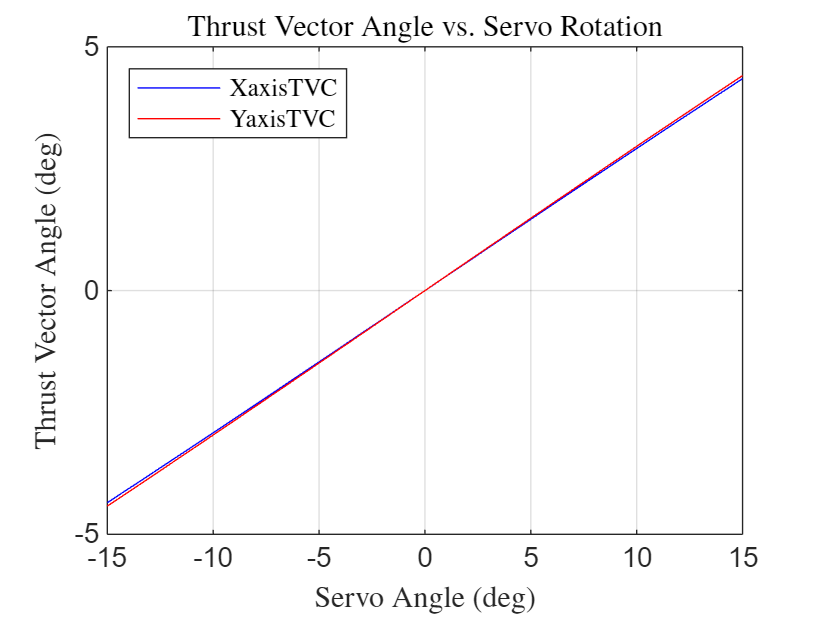

theta1_list = -15:0.1:15;
Xaxis_phi_list = zeros(size(theta1_list));
Yaxis_phi_list = zeros(size(theta1_list));

for i = 1:length(theta1_list)
    theta1_deg = theta1_list(i);
    theta1 = deg2rad(theta1_list(i));

    %X-Axis System of Equations
    eqs = @(x) [
        C_Xaxis*sin(theta1) + L_Xaxis*cos(x(1)) - L_Xaxis - R_Xaxis*sin(x(2));
        C_Xaxis*cos(theta1) + L_Xaxis*sin(x(1)) - R_Xaxis*cos(x(2)) + (R_Xaxis - C_Xaxis)
    ];

    %Y-Axis System of Equations
    eqs2 = @(y)[
      C_Yaxis*sin(theta1) + L_Yaxis*cos(y(1))-L_Yaxis-R_Yaxis*sin(y(2));
      C_Yaxis*cos(theta1) + L_Yaxis*sin(y(1))-R_Yaxis-C_Yaxis+R_Yaxis*cos(y(2))
    ];
    % Solve X
    x0 = [0; 0];
    sol = fsolve(eqs, x0, options);
    X_phi = sol(2);

    % Solve Y
    y0 = [0; 0];
    sol = fsolve(eqs2, y0, options);
    Y_phi = sol(2); 

    Xaxis_phi_list(i) = rad2deg(X_phi);
    Yaxis_phi_list(i) = rad2deg(Y_phi);
end

% Plot
figure;
plot(theta1_list, Xaxis_phi_list, 'b-'); hold on;
plot(theta1_list, Yaxis_phi_list, 'r-')
grid on;
xlabel('Servo Angle (deg)', 'Interpreter', 'latex');
ylabel('Thrust Vector Angle (deg)', 'Interpreter', 'latex');
title('Thrust Vector Angle vs. Servo Rotation', 'Interpreter', 'latex');
legend({'XaxisTVC', 'YaxisTVC'}, 'Interpreter', 'latex', 'Location', 'northwest');